# Análisis tendencia espacial de la Cuenca del Río Pánuco

import matlab.io.hdfeos.*;
clearvars -except study_area;

%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13A2';
kml_file = "RH26";
% umbral para ajuste de ventana y datos 
umbral_mapa=0.1;
umbral_datos = 0.09;
% Cargar los datos en los arreglos
anio_inicio = 2000;
m_cargar_datos

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1098 archivos
>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13A2\061\*.hdf
>>>>> Analizando 1098 archivos
>>>>> Obteniendo latitud y longitud
>>> Cargando área de estudio
>>> Área de estudio existente 1


## Procesar la información

% Declaraciones
% Los años que se desean consultar
meses = [4,9];
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por año
arr_prom_septiembre =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));
arr_prom_abril =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));

arr_max_septiembre =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));
arr_max_abril =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));

arr_min_septiembre =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));
arr_min_abril =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));


arr_ndvi_mj(arr_ndvi_mj<=0.001)=nan; 
   
bp=waitbar(0,'Filtrando información'); 

for y= 1:length(anios)
        % Abril 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 4  ); % Abril
        if( ~isempty (tmp))
            % promedio
            arr_prom_abril(:,:,y) = f_mean_3dpp(arr_ndvi_mj (:,:,tmp));            
            % maximo
            arr_max_abril(:,:,y) = f_max_3dpp(arr_ndvi_mj (:,:,tmp));
            % minimo
            arr_min_abril(:,:,y) = f_min_3dpp(arr_ndvi_mj (:,:,tmp));

        end
   
        % Septiembre 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 9  ); 
        if( ~isempty (tmp))
            % promedio
            arr_prom_septiembre(:,:,y) = f_mean_3dpp(arr_ndvi_mj (:,:,tmp));
            % maximo
            arr_max_septiembre(:,:,y) = f_max_3dpp(arr_ndvi_mj (:,:,tmp));
            % minimo
            arr_min_septiembre(:,:,y) = f_min_3dpp(arr_ndvi_mj (:,:,tmp));
             
        end
                 
    waitbar(y/length(anios),bp,sprintf('Año: (%4d) ',anios(y)));

end
close(bp); 


### Resultados

Mostrar mapas de septiembre

tam_letra=10;

inter_color = [-0.005 0.005];
umbral = 0.0016;

[~,ma1,~] = f_reglin_3dpp(arr_prom_septiembre);
ma1(study_area==false)=nan;
alza = sum(ma1>umbral,"all","omitnan") * 100 / total_pixels ;
disminucion = sum(ma1<-umbral,"all","omitnan")* 100 / total_pixels ;
sincambio = sum(ma1>=-umbral & ma1<=umbral,"all","omitnan")* 100 / total_pixels ;
disp("PR SEP: A: "+alza+" D: "+disminucion+" IG: "+sincambio);

PR SEP: A: 32.834 D: 11.6119 IG: 55.5541


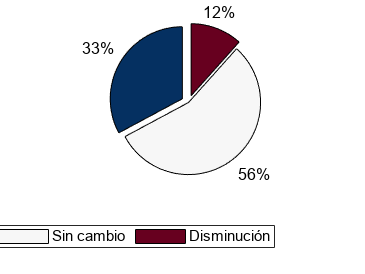


figure;
colormap(m_colmap('divergin',256));
percentValues=[alza  sincambio disminucion];
labels=["Aumento", "Sin cambio" ,"Disminución"];
explode = [1 0 1];
pie(percentValues,explode);
legend(labels,'Location','southoutside','Orientation','horizontal')

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_pie_prom_sept.png",'Resolution',300) 

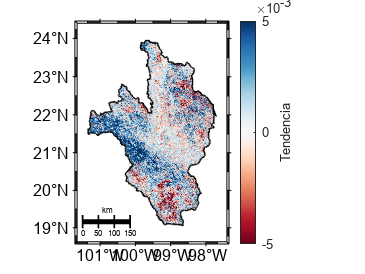

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ma1, flipud(m_colmap('diverging',256)),inter_color ,"Tendencia");
f_draw_kml(dir_data,"RH26");

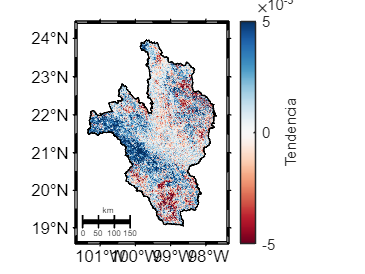

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_reg_lin_prom_sept.png",'Resolution',300); 



[~,ma1,~] = f_reglin_3dpp(arr_max_septiembre);
ma1(study_area==false)=nan;
alza = sum(ma1>umbral,"all","omitnan") * 100 / total_pixels ;
disminucion = sum(ma1<-umbral,"all","omitnan")* 100 / total_pixels ;
sincambio = sum(ma1>=-umbral & ma1<=umbral,"all","omitnan")* 100 / total_pixels ;
disp("MAX SEP: A: "+alza+" D: "+disminucion+" IG: "+sincambio);

MAX SEP: A: 35.3148 D: 9.427 IG: 55.2582


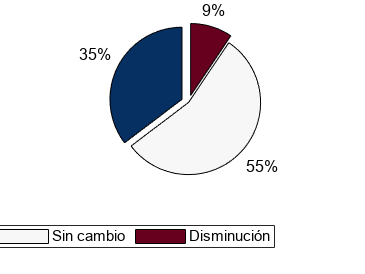


figure;
colormap(m_colmap('divergin',256));
percentValues=[alza  sincambio disminucion];
labels=["Aumento", "Sin cambio" ,"Disminución"];
explode = [1 0 1];
pie(percentValues,explode);
legend(labels,'Location','southoutside','Orientation','horizontal')
ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_pie_max_sept.png",'Resolution',300) 

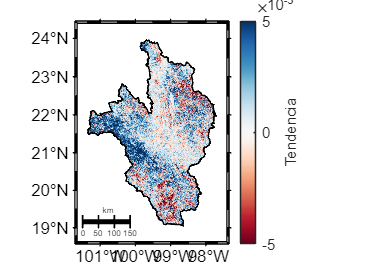


figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ma1, flipud(m_colmap('diverging',256)),inter_color ,"Tendencia");
f_draw_kml(dir_data,"RH26");
%m_dibujar_otras_areas(dir_data);

ax = gca;
ax.FontSize=tam_letra; 

 exportgraphics(ax,"img/at_reg_lin_max_sept.png",'Resolution',300) 

[~,ma1,~] = f_reglin_3dpp(arr_min_septiembre);

ma1(study_area==false)=nan;
alza = sum(ma1>umbral,"all","omitnan") * 100 / total_pixels ;
disminucion = sum(ma1<-umbral,"all","omitnan")* 100 / total_pixels ;
sincambio = sum(ma1>=-umbral & ma1<=umbral,"all","omitnan")* 100 / total_pixels ;
disp("MIN SEPT: A: "+alza+" D: "+disminucion+" IG: "+sincambio);

MIN SEPT: A: 32.306 D: 16.1316 IG: 51.5624


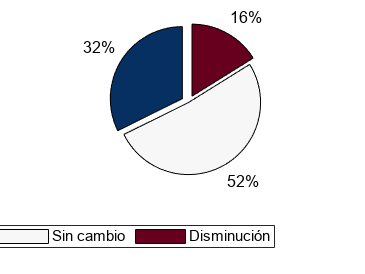


figure;
colormap(m_colmap('divergin',256));
percentValues=[alza  sincambio disminucion];
labels=["Aumento", "Sin cambio" ,"Disminución"];
explode = [1 0 1];
pie(percentValues,explode);
legend(labels,'Location','southoutside','Orientation','horizontal')

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_pie_min_sept.png",'Resolution',300); 

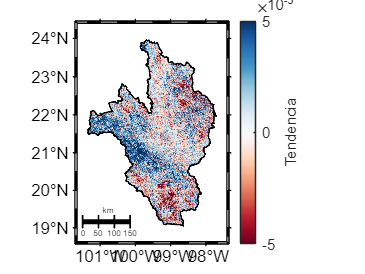


figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ma1, flipud(m_colmap('diverging',256)),inter_color ,"Tendencia");
f_draw_kml(dir_data,"RH26");
ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_reg_lin_min_sept.png",'Resolution',300) 

Mostrar mapas de abril 

[~,ma1,~] = f_reglin_3dpp(arr_max_abril);
ma1(study_area==false)=nan;
alza = sum(ma1>umbral,"all","omitnan") * 100 / total_pixels ;
disminucion = sum(ma1<-umbral,"all","omitnan")* 100 / total_pixels ;
sincambio = sum(ma1>=-umbral & ma1<=umbral,"all","omitnan")* 100 / total_pixels ;
disp("MAX ABR: A: "+alza+" D: "+disminucion+" IG: "+sincambio);

MAX ABR: A: 47.8038 D: 6.0176 IG: 46.1786


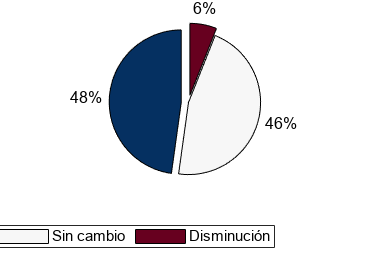


figure;
colormap(m_colmap('divergin',256));
percentValues=[alza  sincambio disminucion];
labels=["Aumento", "Sin cambio" ,"Disminución"];
explode = [1 0 1];
pie(percentValues,explode);
legend(labels,'Location','southoutside','Orientation','horizontal')
ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_pie_max_abril.png",'Resolution',300);

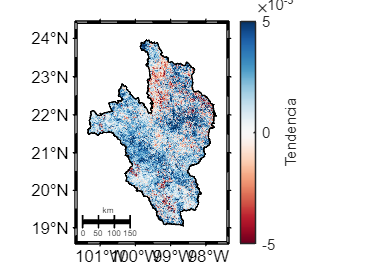


figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ma1, flipud(m_colmap('diverging',256)),inter_color ,"Tendencia");
f_draw_kml(dir_data,"RH26");
ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_reg_lin_max_abril.png",'Resolution',300) 


[~,ma1,~] = f_reglin_3dpp(arr_prom_abril);
ma1(study_area==false)=nan;
alza = sum(ma1>umbral,"all","omitnan") * 100 / total_pixels ;
disminucion = sum(ma1<-umbral,"all","omitnan")* 100 / total_pixels ;
sincambio = sum(ma1>=-umbral & ma1<=umbral,"all","omitnan")* 100 / total_pixels ;
disp("PRO ABR: A: "+alza+" D: "+disminucion+" IG: "+sincambio);

PRO ABR: A: 40.6629 D: 6.8433 IG: 52.4938


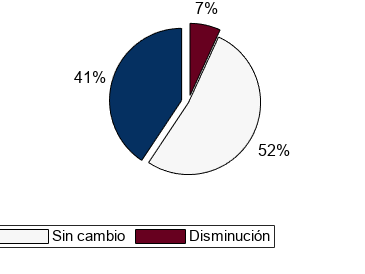


figure;
colormap(m_colmap('divergin',256));
percentValues=[alza  sincambio disminucion];
labels=["Aumento", "Sin cambio" ,"Disminución"];
explode = [1 0 1];
pie(percentValues,explode);
legend(labels,'Location','southoutside','Orientation','horizontal')
ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_pie_prom_abril.png",'Resolution',300);

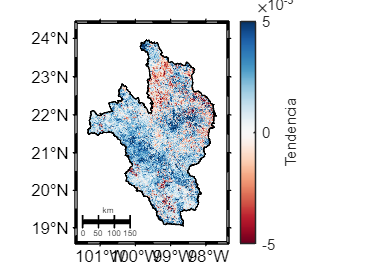


figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ma1, flipud(m_colmap('diverging',256)),inter_color ,"Tendencia");
f_draw_kml(dir_data,"RH26");

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_reg_lin_prom_abril.png",'Resolution',300) 


[ma0,ma1,yaj] = f_reglin_3dpp(arr_min_abril);
ma1(study_area==false)=nan;
alza = sum(ma1>umbral,"all","omitnan") * 100 / total_pixels ;
disminucion = sum(ma1<-umbral,"all","omitnan")* 100 / total_pixels ;
sincambio = sum(ma1>=-umbral & ma1<=umbral,"all","omitnan")* 100 / total_pixels ;
disp("MIN ABR: A: "+alza+" D: "+disminucion+" IG: "+sincambio);

MIN ABR: A: 34.7238 D: 9.5833 IG: 55.6929


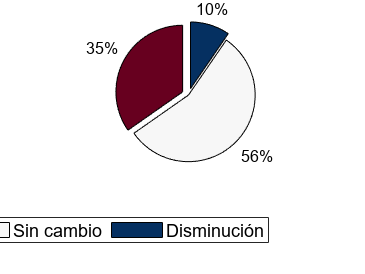

figure;

figure;
colormap(m_colmap('divergin',256));
percentValues=[alza  sincambio disminucion];
labels=["Aumento", "Sin cambio" ,"Disminución"];
explode = [1 0 1];
pie(percentValues,explode);
legend(labels,'Location','southoutside','Orientation','horizontal')

ax = gca;
ax.FontSize=tam_letra+2; 
exportgraphics(ax,"img/at_pie_min_abril.png",'Resolution',300);
f_draw_map(lon_mapa,lat_mapa,lon,lat,ma1, flipud(m_colmap('diverging',256)),inter_color ,"Tendencia");

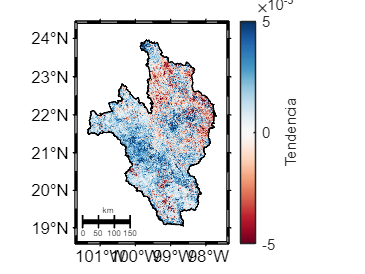

f_draw_kml(dir_data,"RH26");

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(ax,"img/at_reg_lin_min_abril.png",'Resolution',300) 